gain = 0.002769;


gain_Robust =  0.001673; %controller/1.49, plant/1.1, aerodynamic dev/1.19

comp=gain_Robust;
sensor_constant = 0.64;
sensor=sensor_constant;
s = tf("s");
num=[23.85]

num = 23.8500

den=[1 0.184 0]

den =     1.0000    0.1840         0


plant = tf([num], den)

plant =
 
      23.85
  -------------
  s^2 + 0.184 s
 
Continuous-time transfer function.
Model Properties



sys = plant

sys =
 
      23.85
  -------------
  s^2 + 0.184 s
 
Continuous-time transfer function.
Model Properties


open("Lab_2_model");

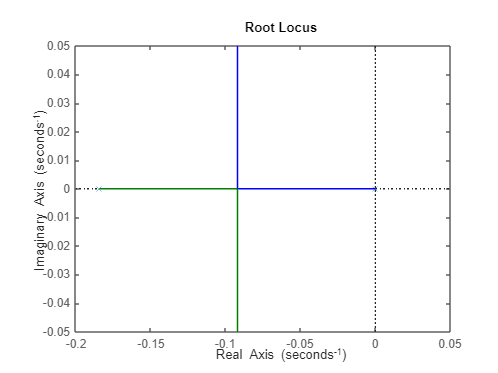

rlocus(sys);

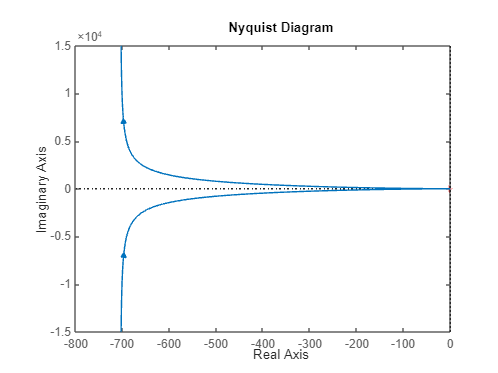

nyquist(sys);


% Calculate gain margin, phase margin, and crossover frequencies
[Gm, Pm, Wcg, Wcp] = margin(sys);
fprintf('Gain Margin: %f dB at frequency %f rad/s\n', 20*log10(Gm), Wcg);

Gain Margin: Inf dB at frequency Inf rad/s


controlSystemDesigner(plant,comp,sensor) 


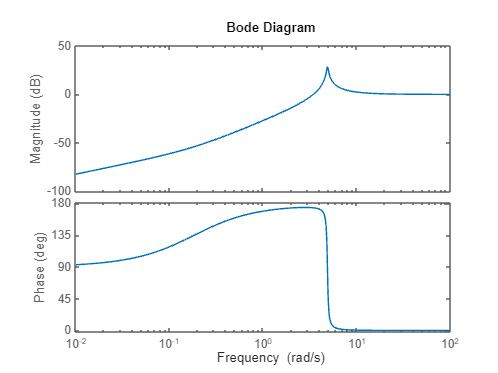

sensitivity= 1/(1+sys);
bode(sensitivity)